# **Analysis of the Burgers equation by LSUN**

First run TanSacNet/code/setpath

Requirements: MATLAB R2022b 

Contact address: Shogo MURAMATSU, Faculty of Engineering, Niigata University, 8050 2-no-cho Ikarashi, Nishi-ku, Niigata, 950-2181, JAPAN http://msiplab.eng.niigata-u.ac.jp  

Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all

% Data folder
datafolder = "../../../data/";


Parameters

% LSUN train
numEpochs = 600;
nCoefs = 2; 
pt = 2;
stride = 2*pt; % Stride (even)

% td-DMD
nDelay = 3;

## Input data

filenameinput = "burgerseq";
if exist(datafolder+filenameinput+".mat","file")~=2
    main_burgerseq_gen(datafolder+filenameinput)
else
    disp("Data found!")
end

Data found!


Sload = load(datafolder+filenameinput,"T","X","DataT","dt","dx");
T = Sload.T;
X = Sload.X;
dt = Sload.dt;
dx = Sload.dx;
DataT = Sload.DataT;

## **Data visualisation**

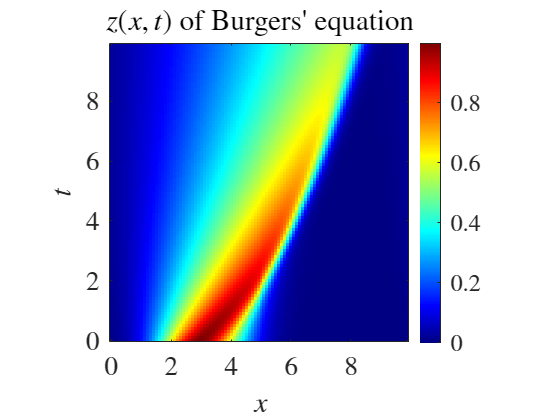

figure
ax = disp_imagesc_(T,X,DataT," $z(x,t)$ of Burgers' equation");
exportgraphics(ax,'fig03a.png')

## LSUN training

nX = size(DataT,2);
filenamelsun = datafolder + "lsunnet_nX"+num2str(nX)+"_stride" + num2str(stride)+"_nCoefs"+num2str(nCoefs) + "_numEpochs" + num2str(numEpochs);
if exist(filenamelsun+".mat","file")~=2
    [analsunnet, synlsunnet,coefMask] = fcn_lsun_train(DataT,stride,nCoefs,numEpochs);
    save(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","numEpochs","coefMask");
else
    disp("LSUN found!")
end

LSUN found!


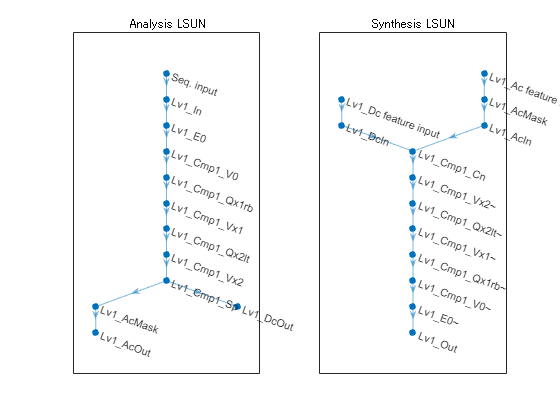

Slsun = load(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","coefMask");
analsunnet = Slsun.analsunnet;
synlsunnet = Slsun.synlsunnet;
coefMask = Slsun.coefMask;
stride = Slsun.stride;
nCoefs = Slsun.nCoefs;


figure
subplot(1,2,1)
plot(analsunnet)
title('Analysis LSUN')
subplot(1,2,2)
plot(synlsunnet)
title('Synthesis LSUN')

### Analysis process

nT = size(DataT,1);
ndim = nX

ndim = 100

analsunseq = zeros(nT,stride,ndim/stride,'like',DataT);
for iT = 1:nT
    [dc,ac] = analsunnet.predict(gpuArray(DataT(iT,:))); % dc: 1 x Pos., ac: Ch. x 1 x Pos
    analsunseq(iT,:,:) = cat(2,permute(dc,[3 1 2]),permute(ac,[2 1 3]));
end
% 3-D array w/ Time x Ch. x Pos.
size(analsunseq)

ans =    100     4    25


### Synthesis process

synlsunnet.Layers(11).InputSize

ans =      3     1    25


synlsunnet.Layers(12).InputSize

ans =      1     1    25


synlsunseq = analsunseq;
DataTaprx = zeros(size(DataT),'like',DataT);
for iT = 1:nT
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

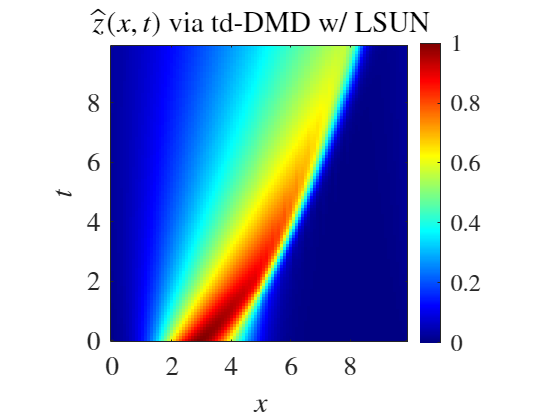

figure
ax = disp_imagesc_(T,X,DataTaprx," $\hat{z}(x,t)$ via td-DMD w/ LSUN");
exportgraphics(ax,'fig03c.png')


% MSE評価
mse(DataT,DataTaprx)

ans = 4.3701e-06

### td-DMD


nRange = size(analsunseq,1); 

size(analsunseq) % K x Ch. x Pos.

ans =    100     4    25


matS = eye(stride);
matS = matS(coefMask==1,:)

matS =      1     0     0     0
     0     0     1     0


dataY = pagemtimes(matS, permute(analsunseq,[2 1 3])); % Ch. x K x Pos.
dataX = reshape(ipermute(dataY,[2 1 3]),nRange,[]) % K x (Ch.Pos.)

dataX =     0.0367   -0.0111    0.1052   -0.0271    0.2564   -0.0520    0.5327   -0.0817    0.9426   -0.0971    1.4211   -0.0411    1.8218   -0.0426    1.9847    0.0524    1.8405    0.2030    1.4111    0.4171    0.8096    0.5862    0.3288    0.4557    0.1194    0.2282    0.0637    0.1059    0.0265    0.0394    0.0118    0.0118    0.0036    0.0029    0.0015    0.0007    0.0000    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0025
    0.0362   -0.0128    0.1063   -0.0268    0.2534   -0.0497    0.5142   -0.0755    0.8932   -0.0886    1.3400   -0.0400    1.7435   -0.0541    1.9623    0.0294    1.8915    0.1899    1.4929    0.4336    0.8626    0.6249    0.3464    0.4829    0.1239    0.2390    0.0663    0.1102    0.0276    0.0409    0.0123    0.0123    0.0038    0.0031    0.0016    0.0007    0.0000    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0023 

% Construction of Hankel matrix
x = dataX;

ts = [];
H = [];
%nRange = size(x,1)-1;
nRange = size(x,1);
for k = 0:nRange-nDelay-1
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end
H

H =     0.0367    0.0362    0.0367    0.0373    0.0381    0.0389    0.0397    0.0406    0.0414    0.0423    0.0431    0.0439    0.0447    0.0454    0.0462    0.0469    0.0476    0.0483    0.0489    0.0495    0.0501    0.0507    0.0513    0.0518    0.0523    0.0528    0.0533    0.0538    0.0542    0.0547    0.0551    0.0555    0.0558    0.0562    0.0566    0.0569    0.0572    0.0575    0.0578    0.0581    0.0584    0.0586    0.0589    0.0591    0.0594    0.0596    0.0598    0.0600    0.0602    0.0604
   -0.0111   -0.0128   -0.0132   -0.0133   -0.0133   -0.0132   -0.0132   -0.0131   -0.0130   -0.0129   -0.0129   -0.0128   -0.0127   -0.0126   -0.0125   -0.0124   -0.0123   -0.0122   -0.0121   -0.0121   -0.0120   -0.0118   -0.0117   -0.0116   -0.0115   -0.0114   -0.0113   -0.0112   -0.0111   -0.0110   -0.0109   -0.0108   -0.0107   -0.0106   -0.0105   -0.0104   -0.0103   -0.0102   -0.0101   -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0094   -0.0093   -0.0092   -0.0091   -0

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.0088   -0.0044   -0.0015    0.0020   -0.0010    0.0013    0.0009   -0.0009    0.0010   -0.0005    0.0011   -0.0002    0.0015   -0.0003   -0.0019   -0.0010    0.0026   -0.0020    0.0037   -0.0031    0.0053   -0.0049    0.0068   -0.0102   -0.0107    0.0099    0.0174    0.0216    0.0238    0.0288    0.0396    0.0548    0.0489    0.0748    0.0489    0.0955    0.0979    0.1011   -0.0645    0.0372    0.0017    0.0775   -0.0488    0.1105   -0.0390    0.0976   -0.1103    0.0936    0.0858   -0.0492
    0.0015   -0.0006    0.0002    0.0002    0.0001    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010   -0.0013   -0.0017   -0.0023    0.0030   -0.0039    0.0049   -0.0060    0.0077   -0.0092    0.0104   -0.0177   -0.0171    0.0179    0.0284    0.0366    0.0389    0.0472    0.0641    0.0872    0.0774    0.1163    0.0740    0.1418    0.1326    0.1571   -0.1202    0.1058   -0.1118    0.0558    0.0598    0.1944   -0.0504    0.1007   -0.1066   -0.0021    0.1415   -0

Sgm =    62.0445         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   27.1003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =    -0.0986    0.1612   -0.1766   -0.1834   -0.1890   -0.1946    0.1998    0.2049    0.2092    0.2128    0.2175    0.2131    0.2239   -0.2178   -0.2128   -0.2130    0.2112   -0.2093    0.1972   -0.1853    0.1838   -0.1636    0.1472   -0.1818   -0.1300    0.1042    0.1256    0.1240    0.0951    0.0831    0.0783    0.0801    0.0508    0.0559    0.0248    0.0390    0.0287    0.0220   -0.0124    0.0065   -0.0002    0.0109   -0.0057    0.0128   -0.0038    0.0059   -0.0062    0.0031    0.0031   -0.0012
   -0.0998    0.1619   -0.1730   -0.1741   -0.1720   -0.1688    0.1633    0.1564    0.1465    0.1347    0.1212    0.1005    0.0856   -0.0617   -0.0365   -0.0114   -0.0158    0.0447   -0.0718    0.0966   -0.1252    0.1413   -0.1495    0.2255    0.1893   -0.1729   -0.2346   -0.2594   -0.2240   -0.2203   -0.2315   -0.2599   -0.1810   -0.2185   -0.1068   -0.1784   -0.1422   -0.1191    0.0700   -0.0397    0.0067   -0.0638    0.0305   -0.0845    0.0263   -0.0450    0.0485   -0.0222   -0.0299    0

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.0088    0.0015   -0.0167    0.0023   -0.0283    0.0030   -0.0438    0.0036   -0.0630    0.0036   -0.0850    0.0009   -0.1081    0.0041   -0.1304    0.0028   -0.1502   -0.0057   -0.1633   -0.0312   -0.1540   -0.0882   -0.1236   -0.1289   -0.1089   -0.1161   -0.1073   -0.1053   -0.0998   -0.0849   -0.0953   -0.0601   -0.0846   -0.0297   -0.0709   -0.0368   -0.0382   -0.0248   -0.0163   -0.0088   -0.0053   -0.0035   -0.0017   -0.0005   -0.0007    0.0001   -0.0017    0.0004   -0.0041    0.0013
   -0.0089    0.0015   -0.0167    0.0022   -0.0281    0.0029   -0.0432    0.0034   -0.0618    0.0035   -0.0830    0.0009   -0.1055    0.0040   -0.1276    0.0029   -0.1478   -0.0054   -0.1617   -0.0306   -0.1534   -0.0876   -0.1239   -0.1290   -0.1097   -0.1166   -0.1084   -0.1061   -0.1011   -0.0858   -0.0969   -0.0609   -0.0864   -0.0300   -0.0726   -0.0377   -0.0397   -0.0258   -0.0176   -0.0092   -0.0062   -0.0037   -0.0020   -0.0006   -0.0008    0.0001   -0.0018    0.0004   -0.0042    

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     0.9921   -0.0133   -0.0076    0.0107   -0.0103    0.0113    0.0116   -0.0123    0.0127   -0.0133    0.0132   -0.0144    0.0144    0.0145   -0.0146    0.0148    0.0145    0.0140    0.0144    0.0151    0.0142    0.0158    0.0148    0.0089   -0.0134   -0.0180    0.0138   -0.0108    0.0102   -0.0095    0.0101   -0.0096    0.0113   -0.0076    0.0134   -0.0059    0.0045   -0.0041   -0.0050   -0.0102    0.0109    0.0024   -0.0037    0.0015    0.0038    0.0027    0.0007    0.0024    0.0007    0.0023
    0.0210    0.9808   -0.0307    0.0094   -0.0172    0.0146    0.0167   -0.0166    0.0176   -0.0180    0.0182   -0.0196    0.0197    0.0197   -0.0200    0.0202    0.0198    0.0191    0.0196    0.0206    0.0193    0.0216    0.0202    0.0121   -0.0182   -0.0246    0.0188   -0.0148    0.0140   -0.0130    0.0138   -0.0131    0.0154   -0.0104    0.0182   -0.0081    0.0062   -0.0057   -0.0068   -0.0139    0.0148    0.0033   -0.0051    0.0020    0.0052    0.0037    0.0010    0.0032    0.00

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay-1
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end

Learnable parameters

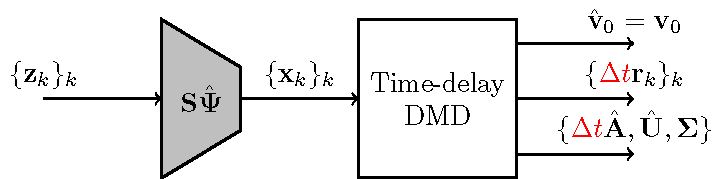

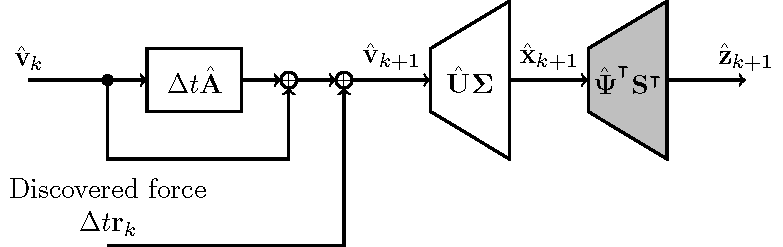

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0986
    0.1612
   -0.1766
   -0.1834
   -0.1890
   -0.1946
    0.1998
    0.2049
    0.2092
    0.2128



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr = 1.0e-15 *

   -0.0416   -0.2776   -0.0694   -0.2220   -0.1388   -0.1804   -0.3053   -0.1527   -0.1388    0.1665   -0.0555   -0.1388   -0.3608   -0.1665    0.1110    0.0833    0.2359   -0.0555    0.4163   -0.1943    0.1804    0.2220    0.2082   -0.0833    0.1249   -0.0971    0.0278         0   -0.0971   -0.0971   -0.0971   -0.0694   -0.0278    0.1110    0.1665   -0.0555   -0.2359   -0.2082    0.0278   -0.1527    0.1249    0.0555   -0.0694   -0.4302    0.2220         0   -0.0833    0.1527         0   -0.1943
         0   -0.0555   -0.0278    0.0555    0.0833   -0.1388    0.1665         0   -0.0555    0.0555   -0.1110    0.3053    0.0555    0.0555    0.0278    0.2498         0   -0.0278   -0.0555   -0.0694    0.2359   -0.1110    0.0416   -0.1388   -0.0555    0.0416   -0.1665    0.3053    0.1527    0.0208    0.2012   -0.0208    0.1527    0.0659    0.1353    0.1700         0    0.0893    0.0544    0.1934   -0.0885   -0.0555    0.1006    0.1249    0.1180    0.0069   -0.3053   -0.0208  


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     0.9921   -0.0133   -0.0076    0.0107   -0.0103    0.0113    0.0116   -0.0123    0.0127   -0.0133    0.0132   -0.0144    0.0144    0.0145   -0.0146    0.0148    0.0145    0.0140    0.0144    0.0151    0.0142    0.0158    0.0148    0.0089   -0.0134   -0.0180    0.0138   -0.0108    0.0102   -0.0095    0.0101   -0.0096    0.0113   -0.0076    0.0134   -0.0059    0.0045   -0.0041   -0.0050   -0.0102    0.0109    0.0024   -0.0037    0.0015    0.0038    0.0027    0.0007    0.0024    0.0007    0.0023
    0.0210    0.9808   -0.0307    0.0094   -0.0172    0.0146    0.0167   -0.0166    0.0176   -0.0180    0.0182   -0.0196    0.0197    0.0197   -0.0200    0.0202    0.0198    0.0191    0.0196    0.0206    0.0193    0.0216    0.0202    0.0121   -0.0182   -0.0246    0.0188   -0.0148    0.0140   -0.0130    0.0138   -0.0131    0.0154   -0.0104    0.0182   -0.0081    0.0062   -0.0057   -0.0068   -0.0139    0.0148    0.0033   -0.0051    0.0020    0.0052    0.0037    0.0010    0.0032    0.00


$$\hat{\mathbf{U}}$$


rRed = nCoefs/stride;
Uhat = U(1:(ndim*rRed),:);
Uhat

Uhat =    -0.0088   -0.0044   -0.0015    0.0020   -0.0010    0.0013    0.0009   -0.0009    0.0010   -0.0005    0.0011   -0.0002    0.0015   -0.0003   -0.0019   -0.0010    0.0026   -0.0020    0.0037   -0.0031    0.0053   -0.0049    0.0068   -0.0102   -0.0107    0.0099    0.0174    0.0216    0.0238    0.0288    0.0396    0.0548    0.0489    0.0748    0.0489    0.0955    0.0979    0.1011   -0.0645    0.0372    0.0017    0.0775   -0.0488    0.1105   -0.0390    0.0976   -0.1103    0.0936    0.0858   -0.0492
    0.0015   -0.0006    0.0002    0.0002    0.0001    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010   -0.0013   -0.0017   -0.0023    0.0030   -0.0039    0.0049   -0.0060    0.0077   -0.0092    0.0104   -0.0177   -0.0171    0.0179    0.0284    0.0366    0.0389    0.0472    0.0641    0.0872    0.0774    0.1163    0.0740    0.1418    0.1326    0.1571   -0.1202    0.1058   -0.1118    0.0558    0.0598    0.1944   -0.0504    0.1007   -0.1066   -0.0021    0.1415  


$$\mathbf{\Sigma}$$


Sgm

Sgm =    62.0445         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   27.1003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

% Reshape results
size(Xhat)  % (K-D) x (Ch.Pos.)

ans =     97    50


nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Xhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataXhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataXhat)

ans =     97     4    25


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataXhat;
DataHatTaprx = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataHatTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

%figure
%disp_imagesc_(T,X,DataHatTaprx,)
% MSE評価
mse(DataT(1:nRangeOut,:),DataHatTaprx)

ans = 4.4303e-06

## Discovered forcing signal

r0 = zeros(size(v0hat),'like',v0hat);
%dtrk = dtr(:,1);
Rhat = (Uhat*Sgm*r0).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    rkp1hat = dtrk/dt;
    Rhat =  cat(1,Rhat,(Uhat*Sgm*rkp1hat).');
    % Update
    rkhat = rkp1hat;
end

% Reshape results
size(Rhat)  % (K-D) x (Ch.Pos.)

ans =     97    50


nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Rhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataQhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataQhat)

ans =     97     4    25


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataQhat;
DataTdfs = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTdfs(iT,:) = synlsunnet.predict(ac,dc);    
end

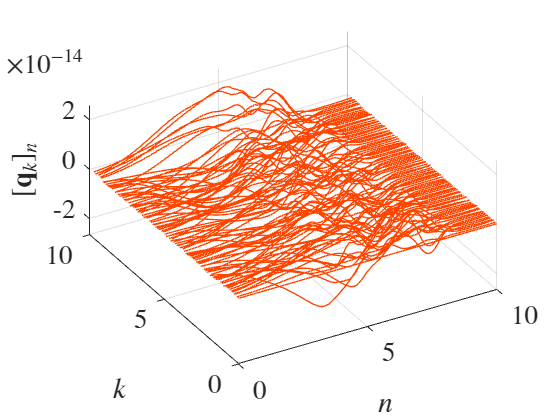


figure
orangered = [255 69 0]/255;
ax = disp_plot3_q_(T(1:size(DataTdfs,1)),X,DataTdfs,orangered);
exportgraphics(ax,'fig04b.png')

disp("||q_k||_2^2/(K-D)")

||q_k||_2^2/(K-D)


size(DataTdfs,1)

ans = 97

norm(DataTdfs,'Fro')/size(DataTdfs,1)

ans = 6.1599e-15

Function definition

function ax = disp_plot3_q_(T,X,DataT,c)
if nargin < 4
 c = 'blue';
end

for idx = 1:length(T)
 plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
 'Color',c,...
 'LineWidth',1)
 hold on
end
xlabel('$n$', 'Interpreter','latex')
ylabel('$k$', 'Interpreter','latex')
zlabel('$[\mathbf{q}_k]_n$', 'Interpreter','latex')
ax = gca;
ax.View = [-30 30];
ax.PlotBoxAspectRatio = [ 2 2 1];
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';

grid on
hold off
end


function ax = disp_imagesc_(T,X,DataT,title_)
imagesc(DataT)
colormap("jet")
cb = colorbar;
cb.TickLabelInterpreter = 'latex';
title(title_,'Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$t$','Interpreter','latex')
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
ax.YDir = 'normal';
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';
end